# Keyword Spotting in Noise Using MFCC and LSTM Networks

This example shows how to identify a keyword in noisy speech using a deep learning network. In particular, the example uses a Bidirectional Long Short-Term Memory (BiLSTM) network and mel frequency cepstral coefficients (MFCC).

## Introduction

Keyword spotting (KWS) is an essential component of voice-assist technologies, where the user speaks a predefined keyword to wake-up a system before speaking a complete command or query to the device.

This example trains a KWS deep network with feature sequences of mel-frequency cepstral coefficients (MFCC). The example also demonstrates how network accuracy in a noisy environment can be improved using data augmentation.

This example uses long short-term memory (LSTM) networks, which are a type of recurrent neural network (RNN) well-suited to study sequence and time-series data. An LSTM network can learn long-term dependencies between time steps of a sequence. An LSTM layer ([lstmLayer](docid:nnet_ref#mw_9f7c5f93-4bf2-4ddb-b922-b1c122668b9a)) can look at the time sequence in the forward direction, while a bidirectional LSTM layer ([`blstmLayer`](docid:nnet_ref#mw_8511c52b-8f87-4919-8cf9-5bc952a6ed99)) can look at the time sequence in both forward and backward directions. This example uses a bidirectional LSTM layer.

The example uses the google Speech Commands Dataset to train the deep learning model. To run the example, you must first download the data set. If you do not want to download the data set or train the network, then you can download and use a pretrained network by opening this example in MATLAB® and running the **Spot Keyword with Pretrained Network** section.

## Spot Keyword with Pretrained Network

Before going into the training process in detail, you will download and use a pretrained keyword spotting network to identify a keyword.

In this example, the keyword to spot is **YES**.

Read a test signal where the keyword is uttered.

[audioIn,fs] = audioread("KeywordSpeech_34s_yes.wav");

% Gentle front-end (won't make audio grainy, keeps formants)
[audioClean, fi] = kws_frontend_filter_soft(audioIn, fs);

fprintf('[SoftFE] In: %.1f dBFS -> Out: %.1f dBFS | xover=%d Hz | maxDeEss=%.1f dB\n', ...
    fi.levelInDb, fi.levelOutDb, fi.deesser.xoverHz, fi.deesser.maxAttenDb);

[SoftFE] In: -22.9 dBFS -> Out: -23.4 dBFS | xover=3500 Hz | maxDeEss=6.0 dB


Download and load the pretrained network, the mean (M) and standard deviation (S) vectors used for feature normalization, as well as 2 audio files used for validating the network later in the example. 

downloadFolder = matlab.internal.examples.downloadSupportFile("audio","KeywordSpotting.zip");
dataFolder = tempdir;
unzip(downloadFolder,dataFolder)
netFolder = fullfile(dataFolder,"KeywordSpotting");
load(fullfile(netFolder,"KWSNet.mat"));

Create an [`audioFeatureExtractor`](docid:audio_ref#mw_b56cd7dc-af31-4da4-a43e-b13debc30322) object to perform feature extraction.

windowLength = 512;
overlapLength = 384;
afe = audioFeatureExtractor(SampleRate=fs, ...
    Window=hann(windowLength,"periodic"),OverlapLength=overlapLength, ...
    mfcc=true,mfccDelta=true,mfccDeltaDelta=true);

Extract features from the test signal and normalize them.

features = extract(afe,audioIn);

features = (features - M)./S;

Compute the keyword spotting binary mask. A mask value of one corresponds to a segment where the keyword was spotted.

mask = classify(KWSNet,features.');

Each sample in the mask corresponds to 128 samples from the speech signal (`windowLength ``- ``overlapLength`).

Expand the mask to the length of the signal.

mask = repmat(mask,windowLength-overlapLength,1);
mask = double(mask) - 1;
mask = mask(:);

Plot the test signal and the mask.

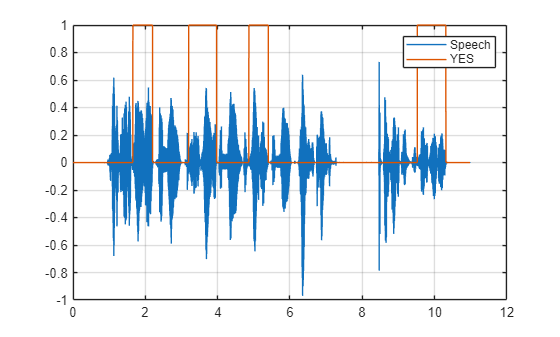

figure
audioIn = audioIn(1:length(mask));
t = (0:length(audioIn)-1)/fs;
plot(t,audioIn)
grid on
hold on
plot(t, mask)
legend("Speech","YES")

Listen to the spotted keyword.

sound(audioIn(mask==1),fs)

## Detect Commands Using Streaming Audio from Microphone

Test your pre-trained command detection network on streaming audio from your microphone. Try saying random words, including the keyword (**YES**).

Call [generateMATLABFunction](docid:audio_ref#mw_09903892-0161-41e5-abc3-9785cd4261e1) on the `audioFeatureExtractor` object to create the feature extraction function. You will use this function in the processing loop.

generateMATLABFunction(afe,"generateKeywordFeatures",IsStreaming=true);

Define an audio device reader that can read audio from your microphone. Set the frame length to the hop length. This enables you to compute a new set of features for every new audio frame from the microphone.

hopLength = windowLength - overlapLength;
frameLength = hopLength;
adr = audioDeviceReader(SampleRate=fs,SamplesPerFrame=frameLength);

Create a scope for visualizing the speech signal and the estimated mask.

scope = timescope(SampleRate=fs, ...
    TimeSpanSource="property", ...
    TimeSpan=5, ...
    TimeSpanOverrunAction="Scroll", ...
    BufferLength=fs*5*2, ...
    ShowLegend=true, ...
    ChannelNames={'Speech','Keyword Mask'}, ...
    YLimits=[-1.2,1.2], ...
    Title="Keyword Spotting");

Define the rate at which you estimate the mask. You will generate a mask once every `numHopsPerUpdate` audio frames.

numHopsPerUpdate = 16;

Initialize a buffer for the audio.

dataBuff = dsp.AsyncBuffer(windowLength);

Initialize a buffer for the computed features.

featureBuff = dsp.AsyncBuffer(numHopsPerUpdate);

Initialize a buffer to manage plotting the audio and the mask.

plotBuff = dsp.AsyncBuffer(numHopsPerUpdate*windowLength);

To run the loop indefinitely, set timeLimit to `Inf`. To stop the simulation, close the scope.

timeLimit = 20;

tic
while toc < timeLimit

    data = adr();
    write(dataBuff,data);
    write(plotBuff,data);

    frame = read(dataBuff,windowLength,overlapLength);
    features = generateKeywordFeatures(frame);
    write(featureBuff,features.');

    if featureBuff.NumUnreadSamples == numHopsPerUpdate
        featureMatrix = read(featureBuff);
        featureMatrix(~isfinite(featureMatrix)) = 0;
        featureMatrix = (featureMatrix - M)./S;

        [keywordNet,v] = classifyAndUpdateState(KWSNet,featureMatrix.');
        v = double(v) - 1;
        v = repmat(v,hopLength,1);
        v = v(:);
        v = mode(v);
        v = repmat(v,numHopsPerUpdate*hopLength,1);

        data = read(plotBuff);
        scope([data,v]);

        if ~isVisible(scope)
            break;
        end
    end
end
hide(scope)

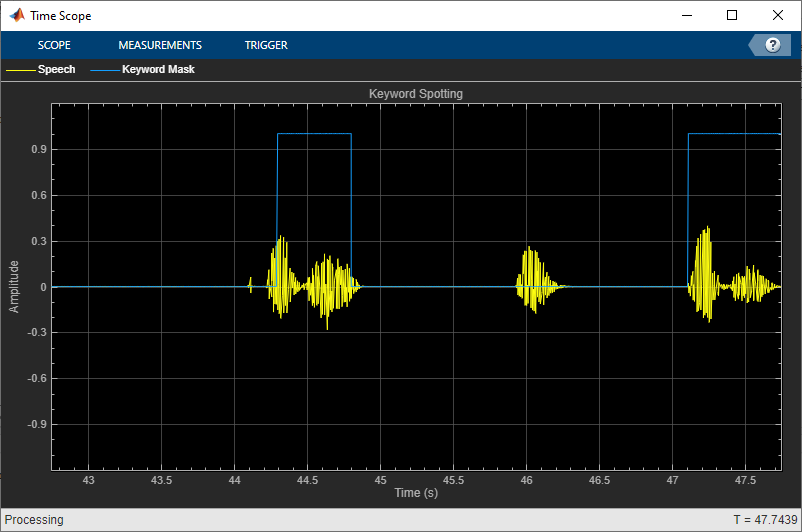

In the rest of the example, you will learn how to train the keyword spotting network.

## Training Process Summary

The training process goes through the following steps:

- Inspect a "gold standard" keyword spotting baseline on a validation signal.

- Create training utterances from a noise-free dataset.

- Train a keyword spotting LSTM network using MFCC sequences extracted from those utterances.

- Check the network accuracy by comparing the validation baseline to the output of the network when applied to the validation signal.

- Check the network accuracy for a validation signal corrupted by noise.

- Augment the training dataset by injecting noise to the speech data using [`audioDataAugmenter`](docid:audio_ref#mw_17a0d8a0-7ba7-4400-a3f3-2b63eaa6df23).

- Retrain the network with the augmented dataset.

- Verify that the retrained network now yields higher accuracy when applied to the noisy validation signal. 

## Inspect the Validation Signal

You use a sample speech signal to validate the KWS network. The validation signal consists 34 seconds of speech with the keyword **YES** appearing intermittently.

Load the validation signal.

[audioIn,fs] = audioread("KeywordSpeech_34s_yes.wav");

Listen to the signal.

sound(audioIn,fs)

Visualize the signal.

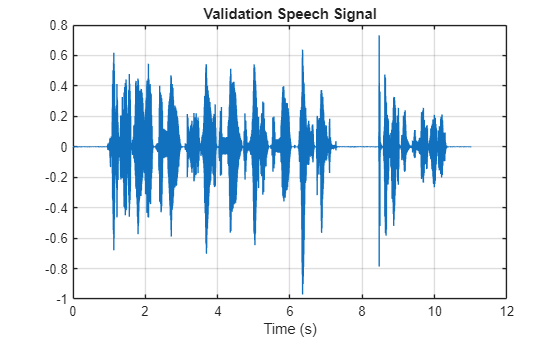

figure
t = (1/fs)*(0:length(audioIn)-1);
plot(t,audioIn);
grid on
xlabel("Time (s)")
title("Validation Speech Signal")

## Inspect the KWS Baseline

Load the KWS baseline. This baseline was obtained using [`speech2text`](https://www.mathworks.com/matlabcentral/fileexchange/65266-speech2text) and [Signal Labeler](docid:signal_ref#mw_cecb4589-4122-4388-95da-2a5796c6e3e2). For a related example, see [Label Spoken Words in Audio Signals](docid:signal_ug#mw_8823bb48-e921-4d12-a69f-00bd24dd802c).

load("KWSBaseline.mat","KWSBaseline")

The baseline is a logical vector of the same length as the validation audio signal. Segments in `audioIn` where the keyword is uttered are set to one in `KWSBaseline`.

Visualize the speech signal along with the KWS baseline.

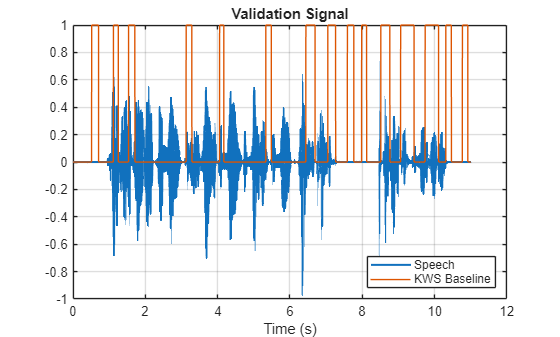

% ===== Robust align + plot (no horzcat dimension errors) =====

% 1) Ensure mono column audio (double) and time vector
if size(audioIn,2) > 1, audioIn = mean(audioIn,2); end
audioIn = double(audioIn(:));
assert(exist('fs','var')==1 && ~isempty(fs), 'fs (sample rate) must be defined.');
Nsig = numel(audioIn);
t    = (0:Nsig-1).'/fs;

% 2) Get/guess hopLength (used if baseline is per-frame)
if exist('hopLength','var')~=1 || isempty(hopLength) || hopLength<=0
    if exist('windowLength','var')==1 && exist('overlapLength','var')==1 ...
            && ~isempty(windowLength) && ~isempty(overlapLength)
        hopLength = max(1, windowLength - overlapLength);
    else
        % sensible default for 16 kHz, 512/384 -> hop ≈ 128
        hopLength = max(1, round(0.008*fs)); 
    end
end

% 3) Coerce KWSBaseline to a column and align to sample timeline
KWSBaseline = double(KWSBaseline(:));
Nbase = numel(KWSBaseline);

if Nbase == 0
    baselineSamples = zeros(Nsig,1);
elseif Nbase == Nsig
    baselineSamples = KWSBaseline;
elseif abs(Nbase*hopLength - Nsig) <= max(hopLength, round(0.01*Nsig))
    % Case A: baseline is per-frame -> upsample by hopLength
    baselineSamples = repelem(KWSBaseline, hopLength);
else
    % Case B: different duration/rate -> length-resample (stepwise)
    xi = linspace(0,1,Nbase);
    xo = linspace(0,1,Nsig);
    baselineSamples = interp1(xi, KWSBaseline, xo, 'previous', 'extrap');
end

% 4) Final trim/pad to exact audio length (prevents horzcat mismatch)
if numel(baselineSamples) < Nsig
    baselineSamples(end+1:Nsig,1) = baselineSamples(end);
elseif numel(baselineSamples) > Nsig
    baselineSamples = baselineSamples(1:Nsig);
end

% 5) Optional: offset baseline so it's visible under the waveform
% baselineForPlot = baselineSamples*0.8 - 0.9;   % shows near -1
baselineForPlot = baselineSamples;               % plain 0/1

% 6) Plot cleanly (separate lines; no horzcat needed)
fig = figure;
plot(t, audioIn, 'DisplayName','Speech', 'LineWidth',1.5); hold on; grid on
plot(t, baselineForPlot, 'DisplayName','KWS Baseline');
xlabel('Time (s)')
legend('Location','southeast')
title('Validation Signal')

The objective of the network that you train is to output a KWS mask of zeros and ones like this baseline.

## Supporting Functions

#### Synthesize Sentence

function [sentence,mask] = synthesizeSentence(adsKeyword,adsOther,fs,minlength)

% Read one keyword
keyword = read(adsKeyword);
keyword = keyword./max(abs(keyword));

% Identify region of interest
speechIndices = detectSpeech(keyword,fs);
if isempty(speechIndices) || diff(speechIndices(1,:)) <= minlength
    speechIndices = [1,length(keyword)];
end
keyword = keyword(speechIndices(1,1):speechIndices(1,2));

% Pick a random number of other words (between 0 and 10)
numWords = randi([0,10]);
% Pick where to insert keyword
loc = randi([1,numWords+1]);
sentence = [];
mask = [];
for index = 1:numWords+1
    if index==loc
        sentence = [sentence;keyword];
        newMask = ones(size(keyword));
        mask = [mask;newMask];
    else
        other = read(adsOther);
        other = other./max(abs(other));
        sentence = [sentence;other];
        mask = [mask;zeros(size(other))];
    end
end
end


mmands: A public dataset for single-word speech recognition", 2017. Available from [https://storage.googleapis.com/download.tensorflow.org/data/speech_commands_v0.01.tar.gz](https://storage.googleapis.com/download.tensorflow.org/data/speech_commands_v0.01.tar.gz). Copyright Google 2017. The Speech Commands Dataset is licensed under the Creative Commons Attribution 4.0 license.

*Copyright 2019-2023 The MathWorks, Inc.*